# JPEG Demo

Loading an RGB image

%clear variables
rgb_in = imread('coffee.bmp');

Colorspace transformation

ycbcr = rgb2ycbcr(rgb_in);
y = ycbcr(:,:,1);
cb = ycbcr(:,:,2);
cr = ycbcr(:,:,3);

Displaying

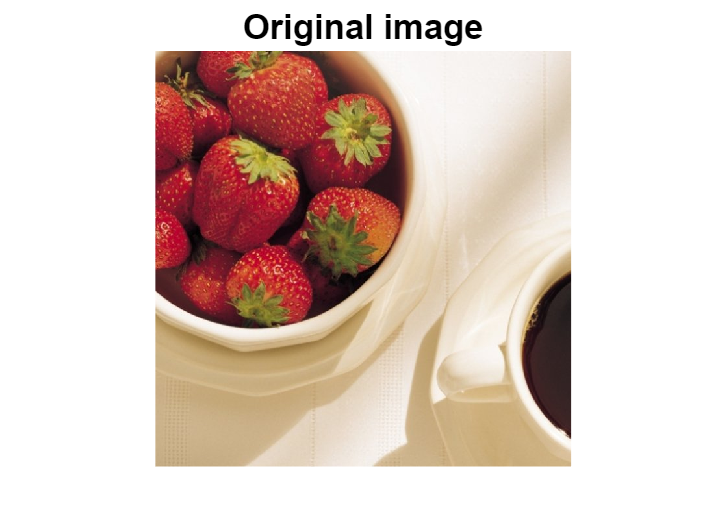

figure(1); image(rgb_in); axis image; axis off; title('Original image')%impixelinfo

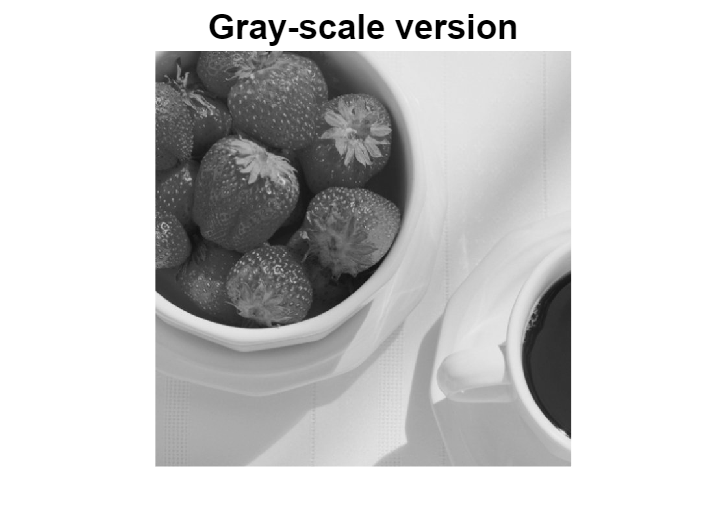

figure(2); image(y); colormap("gray"); axis image; axis off; title('Gray-scale version')%impixelinfo 

Removing average

y0 = double(y)-128; 

Computing DCT

dctfun = @(block_struct) dct2(block_struct.data);
blk_dct = blockproc(double(y0),[8 8], dctfun);

Show a block

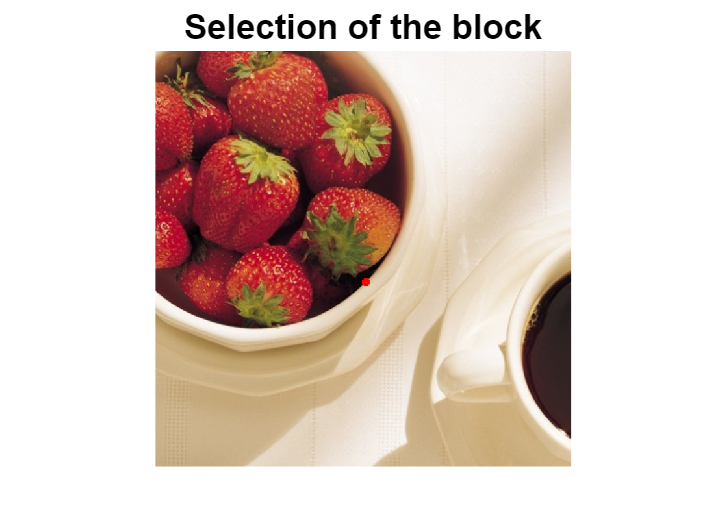

drbx = @(x1,x2,y1,y2) line([x1 x1 x1 x2; x2 x2 x1 x2],[y1 y2 y1 y1; y1 y2 y2 y2]);
rowPos = 353;
colPos = 321;
 

figure(3); image(rgb_in); axis image; axis off; 
hold on; h=drbx(colPos,colPos+7,rowPos,rowPos+7); hold off;
set(h,'linewidth',1,'color', 'red'); title('Selection of the block')

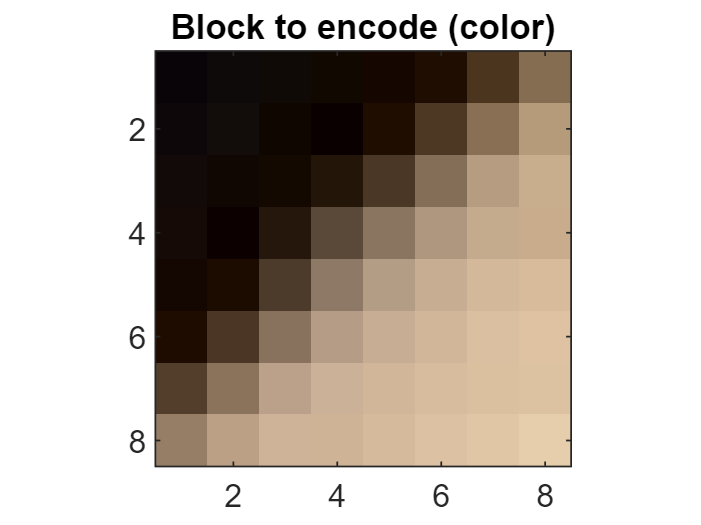

figure(4); image(rgb_in(rowPos:rowPos+7,colPos:colPos+7,:));  axis image; title('Block to encode (color)')

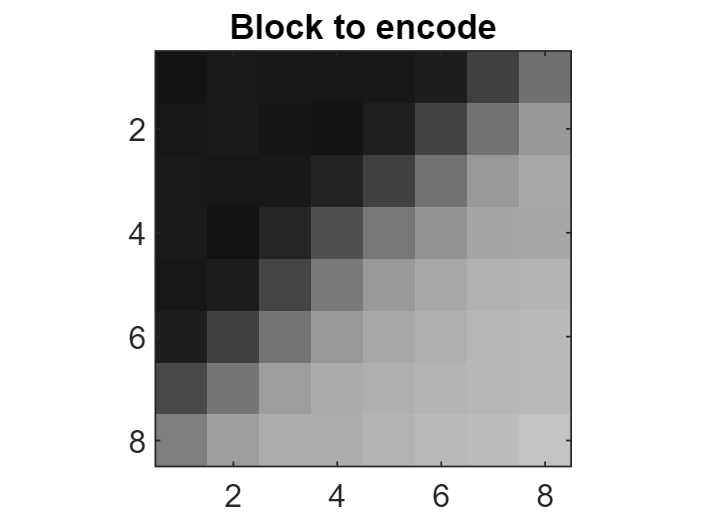

grayBlock = double(y(rowPos:rowPos+7,colPos:colPos+7,:));
figure(5); image(grayBlock); colormap(gray); axis image; title('Block to encode')

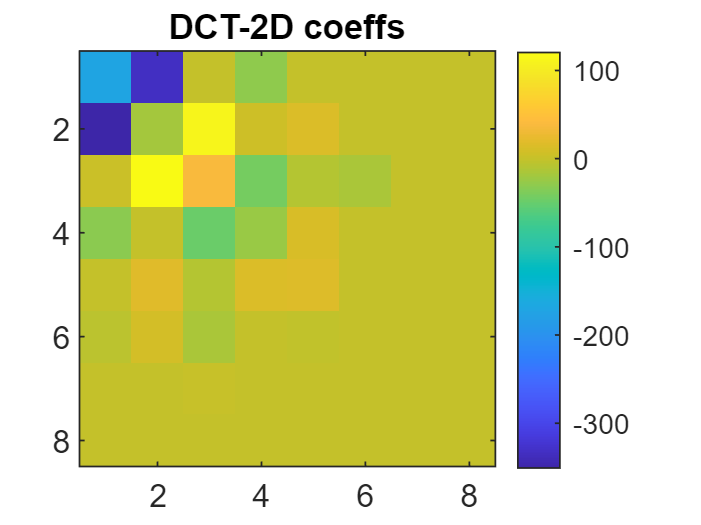

figure(6); imagesc((blk_dct(rowPos:rowPos+7,colPos:colPos+7)));  colorbar; axis image; title('DCT-2D coeffs')

Quantization table

q_mtx1 =     [16 11 10 16 24 40 51 61; 
            12 12 14 19 26 58 60 55;
            14 13 16 24 40 57 69 56; 
            14 17 22 29 51 87 80 62;
            18 22 37 56 68 109 103 77;
            24 35 55 64 81 104 113 92;
            49 64 78 87 103 121 120 101;
            72 92 95 98 112 100 103 99];

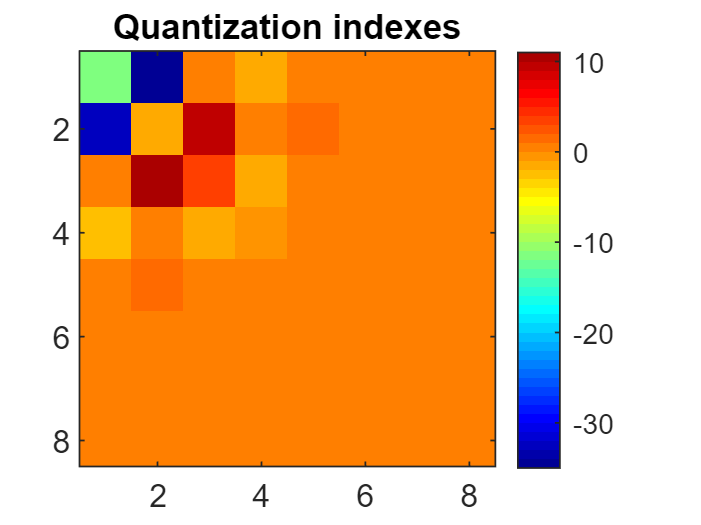

Q = 56;
SF = (Q==100)+(Q<=99&&Q>50)*(200-2*Q)+ (Q<=50)*(5000/Q);
q_mtx = q_mtx1*SF/100;
qfun = @(block_struct) round(block_struct.data./q_mtx);
quant_dct = blockproc(blk_dct,[8 8], qfun);

figure(7); imagesc(quant_dct(rowPos:rowPos+7,colPos:colPos+7));  
blk= quant_dct(rowPos:rowPos+7,colPos:colPos+7); nColors = max(blk(:))-min(blk(:)); 
colormap(jet( nColors));
colorbar; axis image; title('Quantization indexes');% impixelinfo; 

zigzagscan(blk)

ans =    -12   -33   -35     0    -2     0    -3    11     9    -2     0     0     3     0     0     0     1    -2    -2     1     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


bits=block_entropy_coding(blk,33)

DC coding
DC_P	Cat	Bits
-45	      6	1110010010
AC coding
#AC	Run	Cat	Value	Bits
  1	  0	  6	-33		1111000 011110
  2	  0	  6	-35		1111000 011100
  3	  1	  2	 -2		11011 01
  4	  1	  2	 -3		11011 00
  5	  0	  4	 11		1011 1011
  6	  0	  4	  9		1011 1001
  7	  0	  2	 -2		01 01
  8	  2	  2	  3		11111001 11
  9	  3	  1	  1		111010 1
 10	  0	  2	 -2		01 01
 11	  0	  2	 -2		01 01
 12	  0	  1	  1		00 1
 13	  4	  1	 -1		111011 0
EOB                                     1010


bits = '1110010010111100001111011110000111001101101110110010111011101110010101111110011111101010101010100111101101010'

bpp = numel(bits)/64

bpp = 1.7031

#### Image reconstruction

iqfun = @(block_struct)  q_mtx.*(block_struct.data);
iqData =  blockproc(quant_dct,[8 8], iqfun);
idctfun = @(block_struct) idct2( double(block_struct.data) );
reconstruct = uint8(blockproc(iqData,[8 8], idctfun)+128);


Displaying results

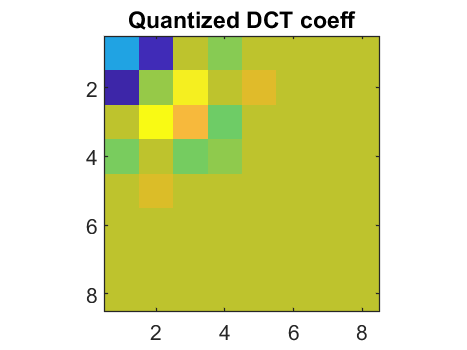

figure(8); imagesc(iqData(rowPos:rowPos+7,colPos:colPos+7)); axis image; title('Quantized DCT coeff');

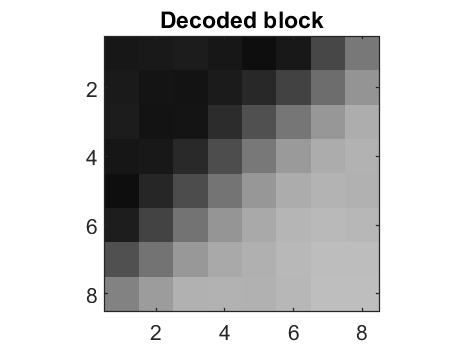

figure(9); image(reconstruct(rowPos:rowPos+7,colPos:colPos+7)); axis image; title('Decoded block'); colormap("gray")

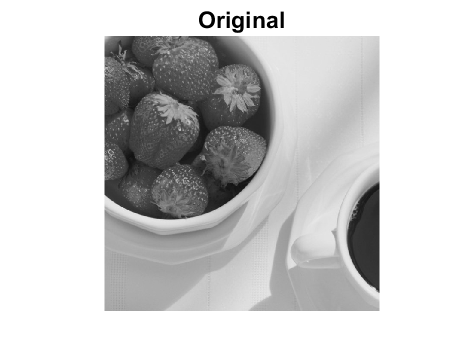

figure(10); image(y); colormap("gray"); axis image; axis off; title('Original') 

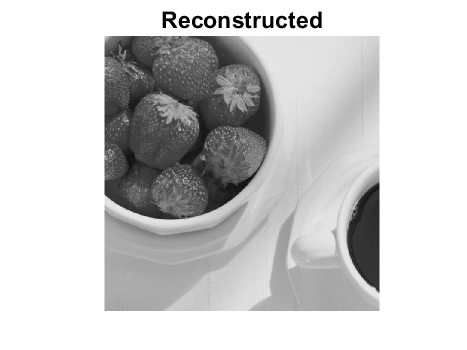

figure(11); image(reconstruct); colormap("gray"); axis image; axis off; title('Reconstructed') 

MSE = mean((y(:)-reconstruct(:)).^2) 

MSE = 2.5251

PSNR = 10*log10(255*255/MSE)

PSNR = 44.1080